A1 = [3.5 9.8;
      7.9 3.1]

A1 =     3.5000    9.8000
    7.9000    3.1000


[V,E] = eig(A1)

V =     0.7516   -0.7365
    0.6596    0.6765


E =    12.1011         0
         0   -5.5011


sum(sum(E))

ans = 6.6000

clear; clc;
x0 = 0;
y0 = 1;
xf = 4;
yf = 3;

dy = @(x,Y) [Y(2); 5*x-2*Y(1)];

z1 = 0;
[x1, y1] = ode45(dy, [x0 xf], [y0 z1]);
y1end = y1(end,1);

z2 = 0.001;
[x2, y2] = ode45(dy, [x0 xf], [y0 z2]);
y2end = y2(end,1);

zactual = z1 + (z2 - z1)/(y2end - y1end)*(yf-y1end)

zactual = 21.3459

clear; clc;
I1 = 4/3*-0.6798 -1/3*-0.9215

I1 = -0.5992

I2 = 4/3*-0.6348-1/3*-0.6798

I2 = -0.6198

I3 = 16/15*I2-1/15*I1

I3 = -0.6212

clear; clc;

x1 =[1.86	2.77	4.24	7.42	8.67];
y1 =[6.86	1.13	1.7	6.92	3.9];
der = diff(y1)./diff(x1)

der =    -6.2967    0.3878    1.6415   -2.4160


sum(der)

ans = -6.6834

clear, clc

A = [-2 1 0;
     1 -2 1;
     0 1 -2;]

A =     -2     1     0
     1    -2     1
     0     1    -2


b = [-20*(3^2)+160*3-240-250;
     -20*(4^2)+160*4-240;
     -20*(5^2)+160*5-240-200];
T = A\b

T =   137.5000
   85.0000
  112.5000


T = [250 T' 200]

T =   250.0000  137.5000   85.0000  112.5000  200.0000


xVal = [2 3 4 5 6];







plot(xVal,T)
hold on;
syms t(x)

ode = diff(t, x, 2) == 80-20*(x-4)^2;

cond1 = t(2) == 250;
cond2 = t(6) == 200;
conds=[cond1 cond2];
solution(x)=dsolve(ode, conds)

$$solution(x) = -\frac{5\,x^{4}}{3}+\frac{80\,x^{3}}{3}-120\,x^{2}+\frac{565\,x}{6}+355$$

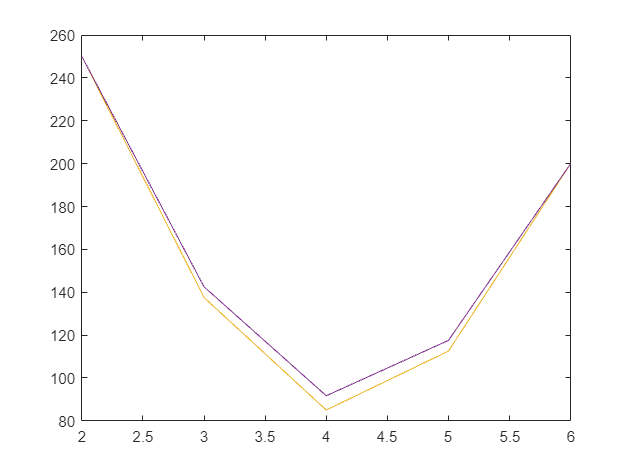

plot(xVal,solution(xVal))